# Plot functions for b3am

Plots wavefield composition, surface wave f-k histograms and dispersion curves, direction of arrival

%%-------------------------------------------------------------------------
% 
% REQUIRED FUNCTIONS:
% - polarplot3d.m (https://nl.mathworks.com/matlabcentral/fileexchange/13200-3d-polar-plot)
% - Crameri library for colour maps (https://nl.mathworks.com/matlabcentral/fileexchange/68546-crameri-perceptually-uniform-scientific-colormaps)
%
% INPUT:
% - path to 'kmax...' files
%
% OUTPUT:
% - dipsersion curves (frequency, wavenumber, uncertainty)
% --> .txt file in directory ../OUT
% - Figures:
% 5)	Bar plot of wavefield composition, relative contributions
% 6)	Bar plot of wavefield composition, absolute contributions
% 7)	Line plot of wavefield composition, absolute contributions
% 8)	Histogram of retrograde Rayleigh waves (wavenumber vs. frequency)
% 9)	Histogram of prograde Rayleigh waves (wavenumber vs. frequency)
% 10)	Histogram of Love waves (wavenumber vs. frequency)
% 11)	Dispersion curves for all three surface wave types (velocity vs. frequency)
% 12)	Polar plots displaying direction of arrival for all 5 wave types (azimuth vs. frequency)
% 
%%-------------------------------------------------------------------------
% Katrin Loer 
% k.loer@tudelft.nl
% Nov 2016 
%
% last modified: 
% - May 2023: comments and clean up for .mlx file, save dispersion 
% curves to .txt file
% - Feb 2024: problem of overlapping columns in polarplot3d.m fixed, new 
% azimuth bins to avoid gaps
%%-------------------------------------------------------------------------

clear
close all

## Please specify:

% Add path to further plotting functions for b3am
addpath ./plot/

% Add paths to Crameri colourmaps
addpath('/Users/kloer/Documents/MATLAB/crameri/');

% INPUT: Set path to B3AM output (kmax files)
dir_in = './Example_Parkfield/OUT/kmax/';

% OUTPUT: Define path for output figures
dir_out = './Figures';

% Choose plot options:
plotcomp = true;           % plot wavefield composition in bar plot
plotcompcurve = true;      % plot wavefield composition as curves
plotkhisto = true;         % plot wavenumber histogram
    histonorm = true;       % normalise each frequency in histogram
plotvdisp = true;          % plot dispersion curves as velocity vs frequency
plotDOA = true;             % plot direction of arrival

% Save as figures?
savefigs = false;

% Number of maxima to be considered
maxflag = 'MAX1';
% 'MAX1': only 1st maximum is considered
% 'NOMAX': all maxima above threshold are considered (see b3am_param.m for threshold applied)

% Minimum signal to noise ratio in histograms
SNR = 1; 
% max(amplitude)/mean(amplitudes) for each frequency --> play with this threshold for maxima in histogram

% Counts or weights/amplitudes in wavefield composition plots
countflag = 'amp'; 
% 'amp' or 'noamp' (weight with amplitudes when counting detections or not)

## Don't change:

if exist(dir_out,'dir')==0
    [SUCCESS,MESSAGE,MESSAGEID] = mkdir(dir_out);
end

if savefigs
    plotpars.maxflag = maxflag;
    plotpars.SNR = SNR;
    plotpars.countflag = countflag;
    save(sprintf('%s/plotpars.mat',dir_out),'plotpars')
end

% Load processing parameters
load([dir_in 'procpars.mat'])

freqs = procpars.freqs;
kmin = min(procpars.kgrid);
kmax = max(procpars.kgrid);

% Load categorical colour palette
load batlowS.mat % for line plotting

infiles = dir([dir_in,'kmax_*.mat']);    
indate = infiles(1).name(9:15);
nw = infiles(1).name(6:7);

nfreq = length(freqs); % number of frequencies (see infiles)
ndays_total = length(infiles)/nfreq;
ndays_stack = ndays_total;
daystep = 1;

% Allocate cell arrays
kr_retro_all = cell(length(freqs),1);
kr_pro_all = cell(length(freqs),1);
kr_love_all = cell(length(freqs),1);
kr_p_all = cell(length(freqs),1);
kr_sv_all = cell(length(freqs),1);

kth_retro_all = cell(length(freqs),1);
kth_pro_all = cell(length(freqs),1);
kth_love_all = cell(length(freqs),1);
kth_p_all = cell(length(freqs),1);
kth_sv_all = cell(length(freqs),1);

a_retro_all = cell(length(freqs),1);
a_pro_all = cell(length(freqs),1);
a_love_all = cell(length(freqs),1);
a_p_all = cell(length(freqs),1);
a_sv_all = cell(length(freqs),1);

e_retro_all = cell(length(freqs),1);
e_pro_all = cell(length(freqs),1);
dip_p_all = cell(length(freqs),1);
dip_sv_all = cell(length(freqs),1);

## WAVE TYPE ANALYSIS

% Loop over frequencies
for ff = 1:nfreq

    f = freqs(ff);
    
    % Loop over total number of days
    for tt = 1:daystep:ndays_total
        
        if ndays_total-tt+1 < ndays_stack
            continue
        end
        
        % Count surface and body waves in frequency bin
        
        c_pro = 0; kr_pro = 0; kth_pro = 0; w_pro = 0;
        c_retro = 0; kr_retro = 0; kth_retro = 0; w_retro = 0;
        c_love = 0; kr_love = 0; kth_love = 0; w_love = 0;
        c_p = 0; kr_p = 0; kth_p = 0; w_p = 0;
        c_sv = 0; kr_sv = 0; kth_sv = 0; w_sv = 0;
        
        % Loop over days to stack
        for dd = tt:min(tt+ndays_stack-1,ndays_total)
            
            datafile = [dir_in, infiles(ff+(dd-1)*nfreq).name];
            if dd == tt
                outfile_help = datafile;
            end
            load(datafile)
            
            if strcmp(maxflag,'MAX1')
                nmax = 1;
            elseif strcmp(maxflag,'MAX3')
                nmax = 3;
            elseif strcmp(maxflag,'MAX5')
                nmax = 5;
            elseif strcmp(maxflag,'NOMAX')
                nmax = size(kr_all,2);
            end
            
            L = size(kr_all,1);
            a0 = 0;
            for n = 1:nmax % number of maxima to count
                for j = 1:L % time windows
                    
                    if kr_all(j,n) <= kmin || kr_all(j,n) >= kmax
                        continue
                    end
                    
                    % P-wave
                    if wave_ind(j,n) == 0
                        c_p = c_p + 1;
                        kr_p(c_p) = kr_all(j,n);
                        kth_p(c_p) = kth_all(j,n);
                        w_p(c_p) = a_all(j,n); % amplitude/weighting factor
                        dip_p(c_p) = pola_all(j,n,2);
                    % Love wave
                    elseif wave_ind(j,n) == 2
                        c_love = c_love + 1;
                        kr_love(c_love) = kr_all(j,n);
                        kth_love(c_love) = kth_all(j,n);
                        w_love(c_love) = a_all(j,n);
                    % SV-wave
                    elseif wave_ind(j,n) == 1
                        c_sv = c_sv + 1;
                        kr_sv(c_sv) = kr_all(j,n);
                        kth_sv(c_sv) = kth_all(j,n);
                        w_sv(c_sv) = a_all(j,n);
                        dip_sv(c_sv) = pola_all(j,n,2);
                    % Prograde Rayleigh wave
                    elseif wave_ind(j,n) == 4
                        c_pro = c_pro + 1;
                        kr_pro(c_pro) = kr_all(j,n);
                        kth_pro(c_pro) = kth_all(j,n);
                        w_pro(c_pro) = a_all(j,n);
                        e_pro(c_pro) = pola_all(j,n,3);
                    % Retrograde Rayleigh wave
                    elseif wave_ind(j,n) == 3
                        c_retro = c_retro + 1;
                        kr_retro(c_retro) = kr_all(j,n);
                        kth_retro(c_retro) = kth_all(j,n);
                        w_retro(c_retro) = a_all(j,n);
                        e_retro(c_retro) = pola_all(j,n,3);
                    end
                    
                end
            end
        end
        
        % Number of wave types
        nwaves(ff,1:5) = [c_retro, c_pro, c_love, c_sv, c_p];
        
        % Amplitudes of wave types
        awaves(ff,1:5) = [sum(w_retro),sum(w_pro),sum(w_love),sum(w_sv),sum(w_p)];
        
        % Wavenumber
        if c_retro > 0; kr_retro_all{ff} = kr_retro; kr_retro_mean(ff) = mean(kr_retro); end
        if c_pro > 0; kr_pro_all{ff} = kr_pro; kr_pro_mean(ff) = mean(kr_pro); end
        if c_love > 0; kr_love_all{ff} = kr_love; kr_love_mean(ff) = mean(kr_love); end
        if c_sv > 0; kr_sv_all{ff} = kr_sv; kr_sv_mean(ff) = mean(kr_sv); end
        if c_p > 0; kr_p_all{ff} = kr_p; kr_p_mean(ff) = mean(kr_p); end
        
        % Ellipticities
        if c_retro > 0; e_retro_all{ff} = e_retro; eretro_m(ff) = mean(e_retro); end
        if c_pro > 0; e_pro_all{ff} = e_pro;  epro_m(ff) = mean(e_pro); end
        
        % Direction of arrival (DOA)
        if c_retro > 0; kth_retro_all{ff} = kth_retro; kth_retro_mean(ff) = mean(kth_retro); end
        if c_pro > 0; kth_pro_all{ff} = kth_pro; kth_pro_mean(ff) = mean(kth_pro); end
        if c_love > 0; kth_love_all{ff} = kth_love; kth_love_mean(ff) = mean(kth_love); end
        if c_sv > 0; kth_sv_all{ff} = kth_sv; kth_sv_mean(ff) = mean(kth_sv); end
        if c_p > 0; kth_p_all{ff} = kth_p; kth_p_mean(ff) = mean(kth_p); end
        
        % Dip for body waves
        if c_sv > 0; dip_sv_all{ff} = dip_sv; dip_sv_mean(ff) = mean(dip_sv); end
        if c_p > 0; dip_p_all{ff} = dip_p; dip_p_mean(ff) = mean(dip_p); end
        
        % Amplitudes
        if c_retro > 0; a_retro_all{ff} = w_retro; end
        if c_pro > 0; a_pro_all{ff} = w_pro;  end
        if c_love > 0; a_love_all{ff} = w_love;  end
        if c_sv > 0; a_sv_all{ff} = w_sv; end
        if c_p > 0; a_p_all{ff} = w_p; end
    end
    
    
end

## Plot wavefield composition

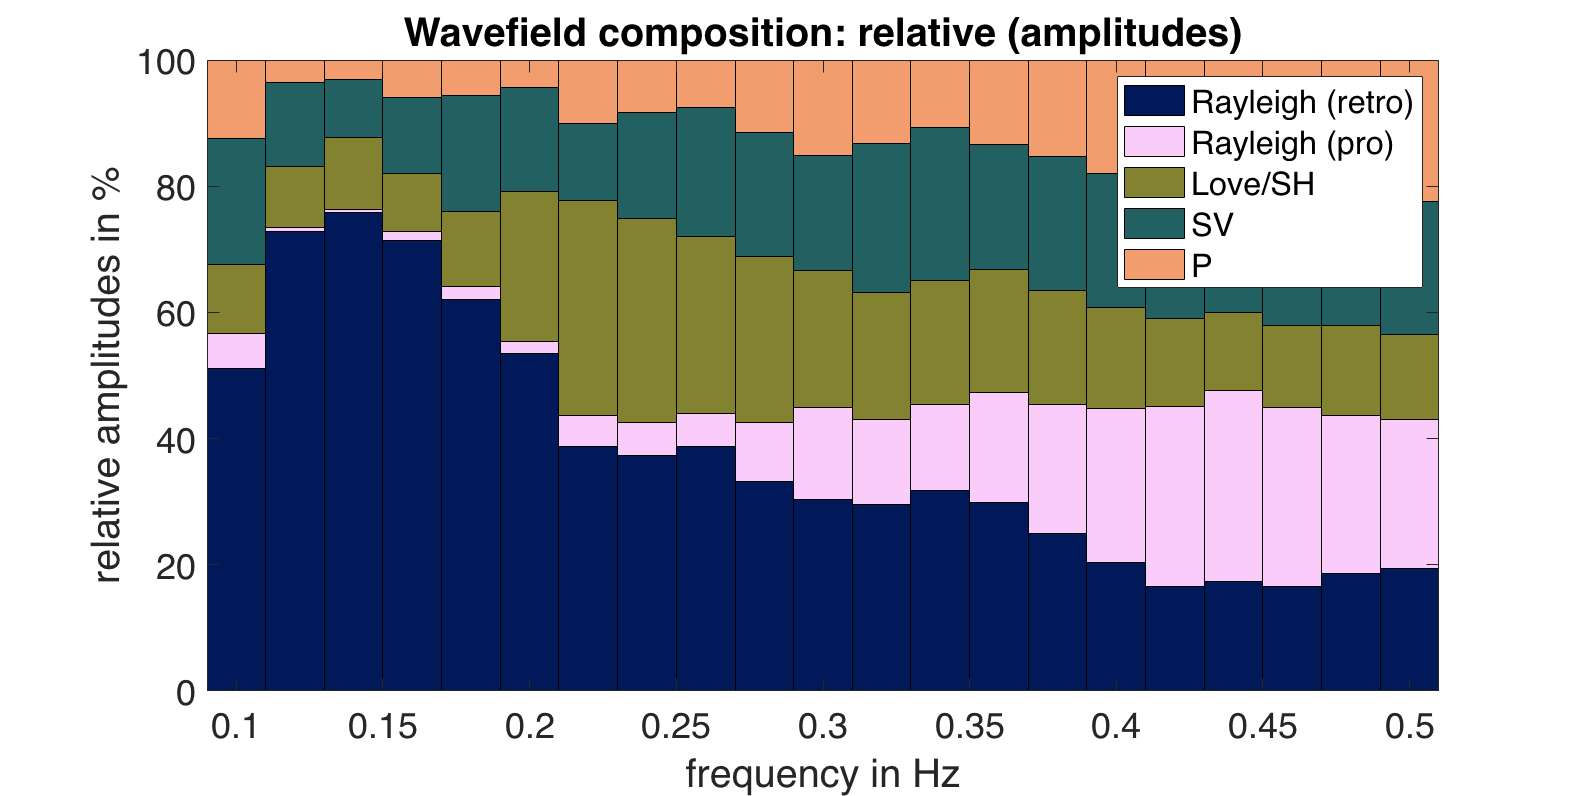

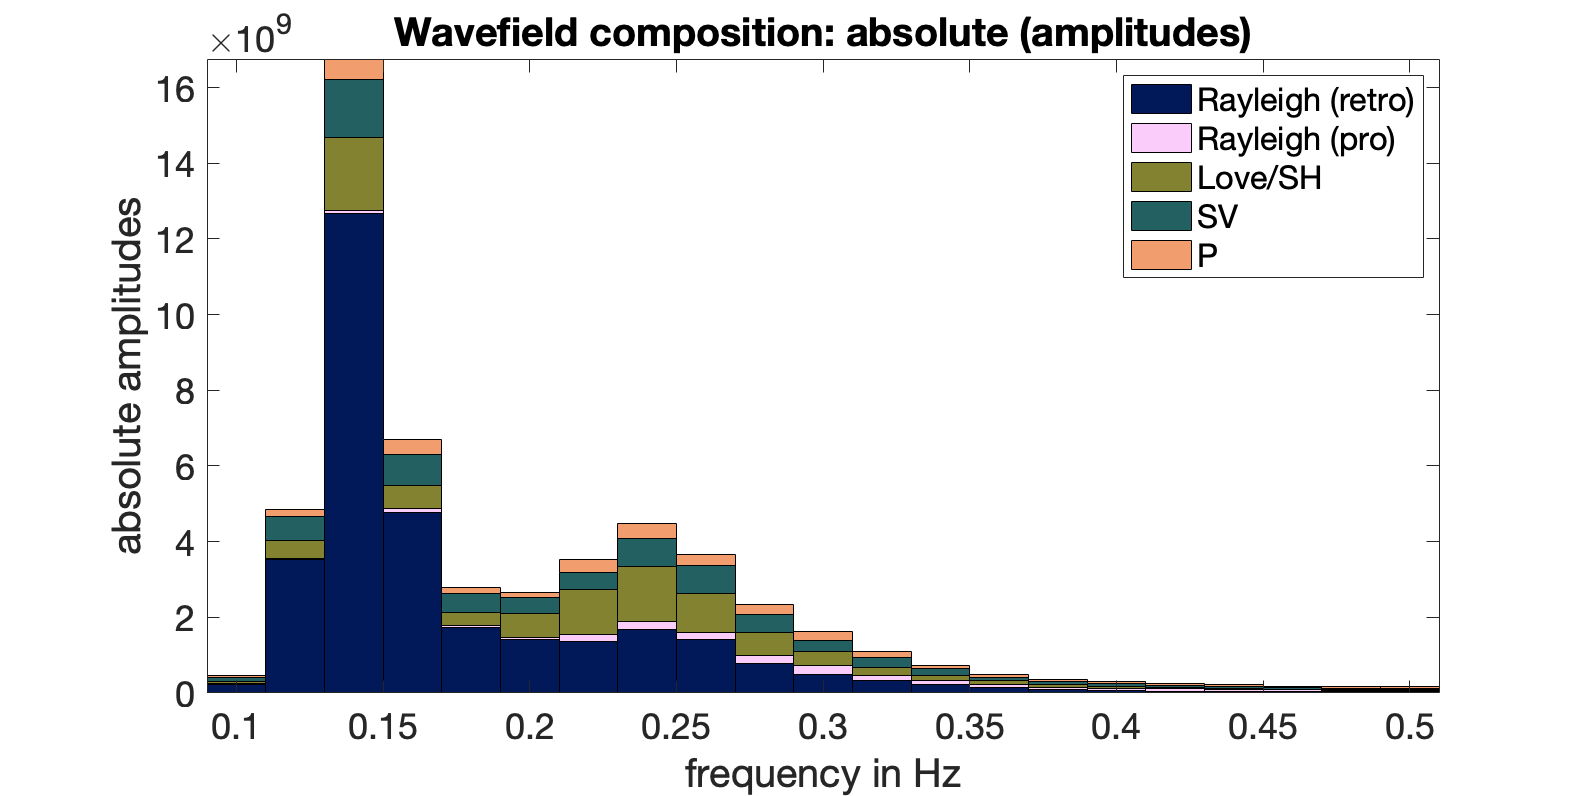

if plotcomp

pfreqs = freqs;

if strcmp(countflag,'amp')    
    pwaves = awaves;
    ystr_rel = 'relative amplitudes in %';
    ystr_abs = 'absolute amplitudes';
    tstr_rel = 'Wavefield composition: relative (amplitudes)';
    tstr_abs = 'Wavefield composition: absolute (amplitudes)';
elseif strcmp(countflag,'noamp')
    pwaves = nwaves;
    ystr_rel = 'relative counts in %';
    ystr_abs = 'absolute counts';
    tstr_rel = 'Wavefield composition: relative (counts)';
    tstr_abs = 'Wavefield composition: absolute (counts)';
end

% Relative counts
%----------------
figure('Color','white','Position',[2000 10 1000 500]);
b = bar(pfreqs,pwaves./sum(pwaves,2).*100,1,'stacked','FaceColor','flat');
for k = 1:5
    b(k).FaceColor = batlowS(k,:);
end
legend('Rayleigh (retro)','Rayleigh (pro)','Love/SH','SV','P','Location','northeast')
set(gca,'Fontsize',18)
xlabel('frequency in Hz')
ylabel(ystr_rel)
axis tight 
title(tstr_rel)

if savefigs
    fname = sprintf('%s/05_comp_%s_rel_%s_%s_%s.png',...
        dir_out,countflag,maxflag,nw,indate);
    print(fname,'-dpng')
end

% Absolute counts
%----------------
figure('Color','white','Position',[2000 10 1000 500]);
b2 = bar(pfreqs,pwaves,1,'stacked','FaceColor','flat');
for k = 1:5
    b2(k).FaceColor = batlowS(k,:);
end
legend('Rayleigh (retro)','Rayleigh (pro)','Love/SH','SV','P','Location','northeast')
set(gca,'Fontsize',18)
xlabel('frequency in Hz')
ylabel(ystr_abs)
axis tight 
title(tstr_abs)

if savefigs
    fname = sprintf('%s/06_comp_%s_abs_%s_%s_%s.png',...
        dir_out,countflag,maxflag,nw,indate);
    print(fname,'-dpng')
end

end

## Plot individual wave contributions (as curves, not bars)

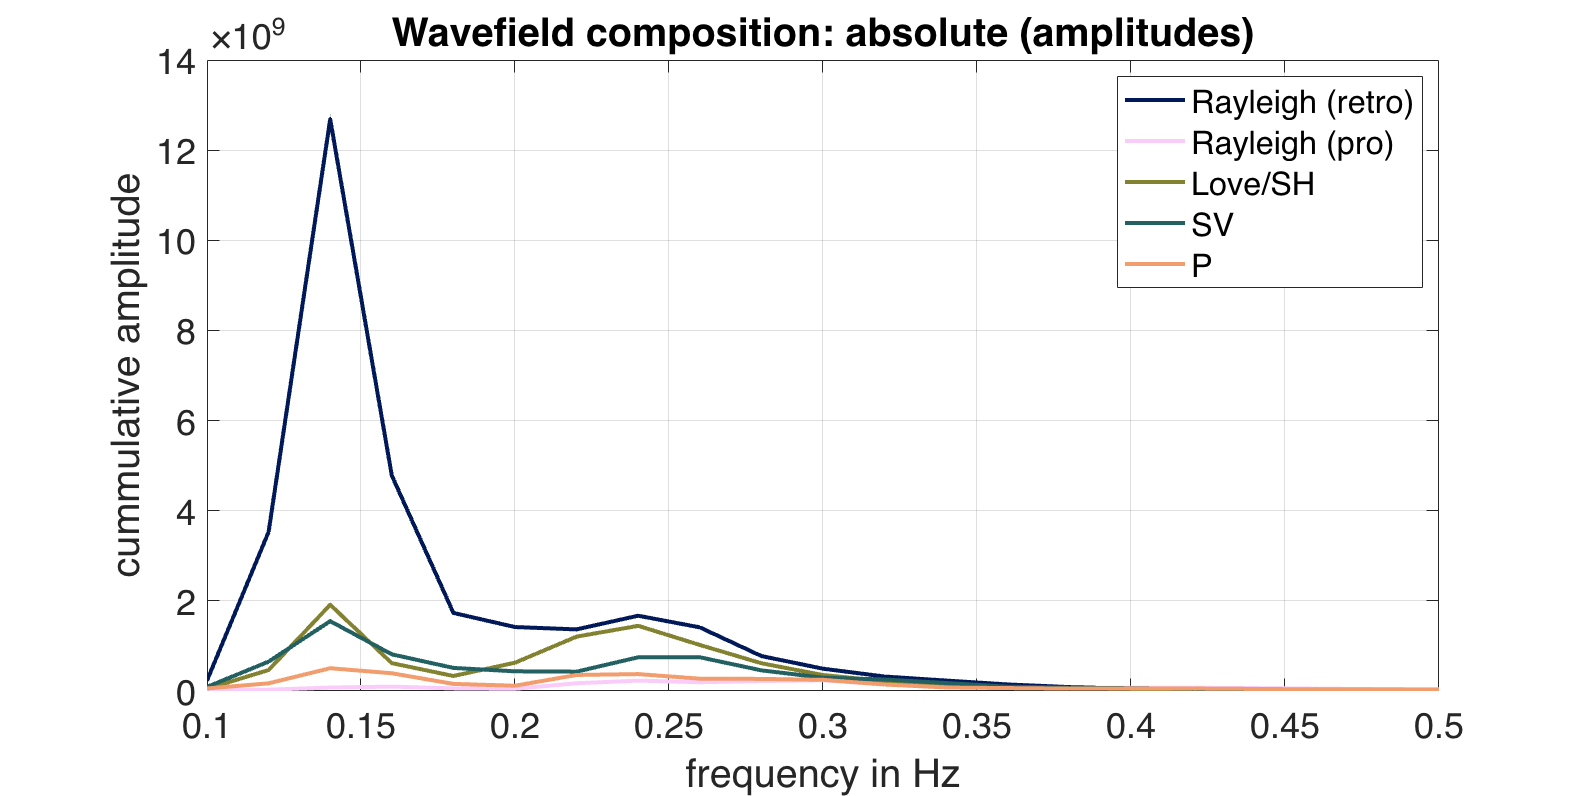

if plotcompcurve

if strcmp(countflag,'noamp')
    
    % Counts
    figure('Color','white','Position',[2000 10 1000 500]);
    title('Wavefield composition: counts')

    hold on
    p1 = plot(freqs,nwaves,'LineWidth',2);
    for k = 1:5
        p1(k).Color = batlowS(k,:);
    end

    legend('Rayleigh (retro)','Rayleigh (pro)','Love/SH','SV','P','Location','northeast')

    box on
    grid on
    xlabel('frequency in Hz')
    ylabel('absolute counts')
    set(gca,'Fontsize',18)
    xlim([min(freqs) max(freqs)])

    if savefigs
        fname = sprintf('%s/07_compcurve_noamp_%s_%s_%s.png',...
            dir_out,maxflag,nw,indate);
        print(fname,'-dpng')
    end

elseif strcmp(countflag,'amp')
    
    % Amplitudes
    figure('Color','white','Position',[2000 10 1000 500]);
    title('Wavefield composition: absolute (amplitudes)')

    hold on
    p2 = plot(freqs,awaves,'LineWidth',2);
    for k = 1:5
        p2(k).Color = batlowS(k,:);
    end
    legend('Rayleigh (retro)', 'Rayleigh (pro)', 'Love/SH', 'SV', 'P')

    box on
    grid on
    xlabel('frequency in Hz')
    ylabel('cummulative amplitude')
    set(gca,'Fontsize',18)
    xlim([min(freqs) max(freqs)])

    if savefigs
        fname = sprintf('%s/07_compcurve_amp_%s_%s_%s.png',...
            dir_out,maxflag,nw,indate);
        print(fname,'-dpng')
    end

end

end

## COMPUTE WAVENUMBER HISTOGRAMS + PICK DISPERSION CURVES

% Create output directory for dispersion curve files
dir_dispout = './OUT';
if exist(dir_dispout,'dir')==0
    mkdir(dir_dispout);
end

% Wavenumber vs frequency
kbins = procpars.kgrid;
kstep = kbins(2)-kbins(1);
prmask = zeros(size(freqs));
ppmask = zeros(size(freqs));
plmask = zeros(size(freqs));
for i = 1:size(freqs,2)
    
    % Wavenumber histograms
    [Nretro,binretro,idxretro]  = histcounts(kr_retro_all{i},kbins);    
    [Npro,binpro,idxpro]        = histcounts(kr_pro_all{i},kbins);    
    [Nlove,binlove,idxlove]     = histcounts(kr_love_all{i},kbins);
    
    % Considering beam response amplitude in wavenumber histogram
    % Retrograd Rayleigh
    if isempty(idxretro) == 0
        Aretro = accumarray(idxretro',a_retro_all{i});
        Aretro(end:numel(Nretro)) = 0;
        % Pick maximum using findpeaks
        Aretro_norm = Aretro./mean(Aretro); % normalise using mean
        [peak,idx,wpeak] = findpeaks(Aretro_norm,'NPeaks',1,'SortStr','descend','MinPeakHeight',SNR,'WidthReference','halfheight');
        if isempty(idx)==0
            kh_retro_max(i) = kbins(idx); % wavenumber of peak
            wmax_retro_k(i) = wpeak * kstep/2; % halfwidth of peak: uncertainty
            prmask(i) = i; % index of peak
        end
        k_retro_amp(i,:) = Aretro;
        k_retro_norm(i,:) = Aretro_norm;
        clear Aretro*
        
        if prmask > 0 
            % Write dispersion curve values to txt file
            fid = fopen([dir_dispout,'/disp_retro.txt'],'w');
            disptxt = cat(2,freqs(prmask > 0)',kh_retro_max(prmask > 0)',wmax_retro_k(prmask > 0)');
            fprintf(fid,'%.3f %.8f %.8f\n',disptxt');
            fclose(fid);
        end
    end
    
    % Prograde Rayleigh
    if isempty(idxpro) == 0
        Apro = accumarray(idxpro',a_pro_all{i});
        Apro(end:numel(Npro)) = 0;
        % Pick maximum using findpeaks
        Apro_norm = Apro./mean(Apro); % normalise using mean
        [peak,idx,wpeak] = findpeaks(Apro_norm,'NPeaks',1,'SortStr','descend','MinPeakHeight',SNR,'WidthReference','halfheight');
        if isempty(idx)==0
            kh_pro_max(i) = kbins(idx); % wavenumber of peak
            wmax_pro_k(i) = wpeak * kstep/2; % halfwidth of peak: uncertainty
            ppmask(i) = i; % index of peak
        end
        k_pro_amp(i,:) = Apro;
        k_pro_norm(i,:) = Apro_norm;
        clear Apro*
        
        if ppmask > 0
            % Write dispersion curve values to txt file
            fid = fopen([dir_dispout,'/disp_pro.txt'],'w');
            disptxt = cat(2,freqs(ppmask > 0)',kh_pro_max(ppmask > 0)',wmax_pro_k(ppmask > 0)');
            fprintf(fid,'%.3f %.8f %.8f\n',disptxt');
            fclose(fid);
        end
    end
    
    % Love
    if isempty(idxlove) == 0
        Alove = accumarray(idxlove',a_love_all{i});
        Alove(end:numel(Nlove)) = 0;
        % Pick maximum using findpeaks
        Alove_norm = Alove./mean(Alove); % normalise using mean
        [peak,idx,wpeak] = findpeaks(Alove_norm,'NPeaks',1,'SortStr','descend','MinPeakHeight',SNR,'WidthReference','halfheight');
        if isempty(idx)==0
            kh_love_max(i) = kbins(idx); % wavenumber of peak
            wmax_love_k(i) = wpeak * kstep/2; % halfwidth of peak: uncertainty
            plmask(i) = i; % index of peak
        end
        k_love_amp(i,:) = Alove;
        k_love_norm(i,:) = Alove_norm;
        clear Alove
        
        if plmask(i)>0
            % Write dispersion curve values to txt file
            fid = fopen([dir_dispout,'/disp_love.txt'],'w');
            disptxt = cat(2,freqs(plmask > 0)',kh_love_max(plmask > 0)',wmax_love_k(plmask > 0)');
            fprintf(fid,'%.3f %.8f %.8f\n',disptxt');
            fclose(fid);
        end
    end
    
end

## Plot wavenumber histograms

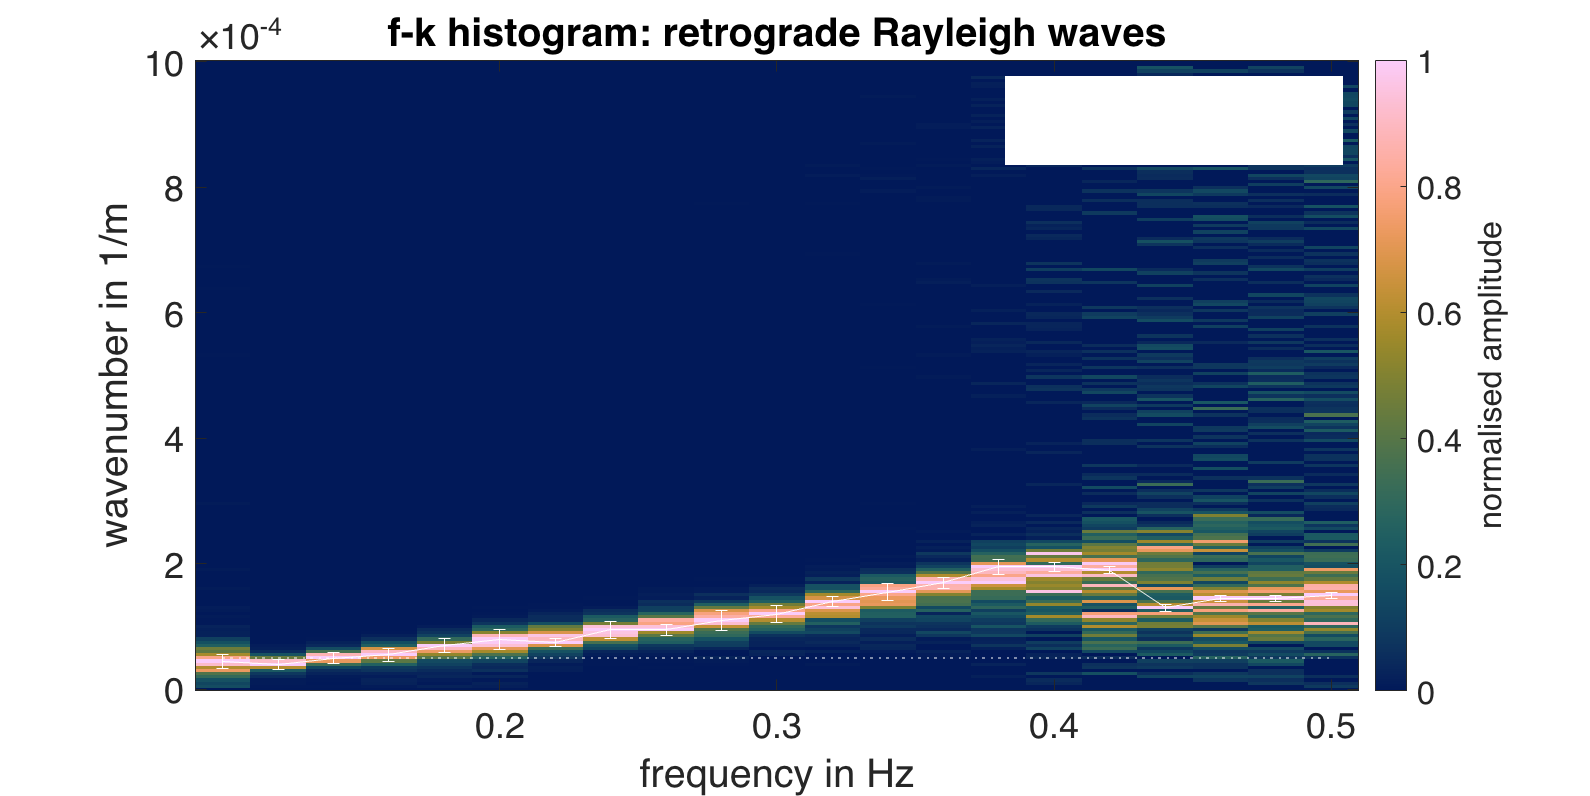

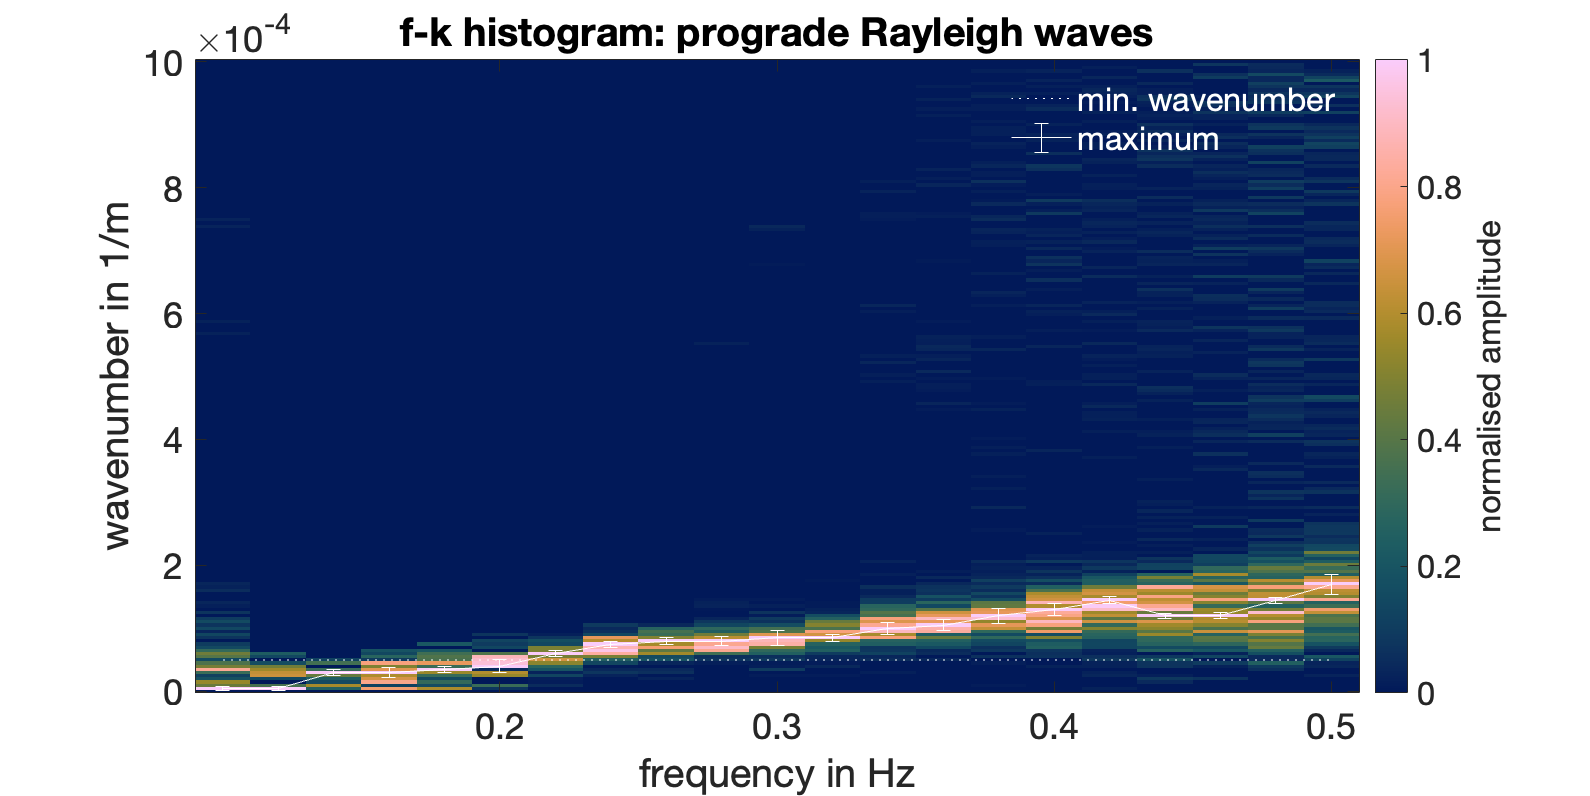

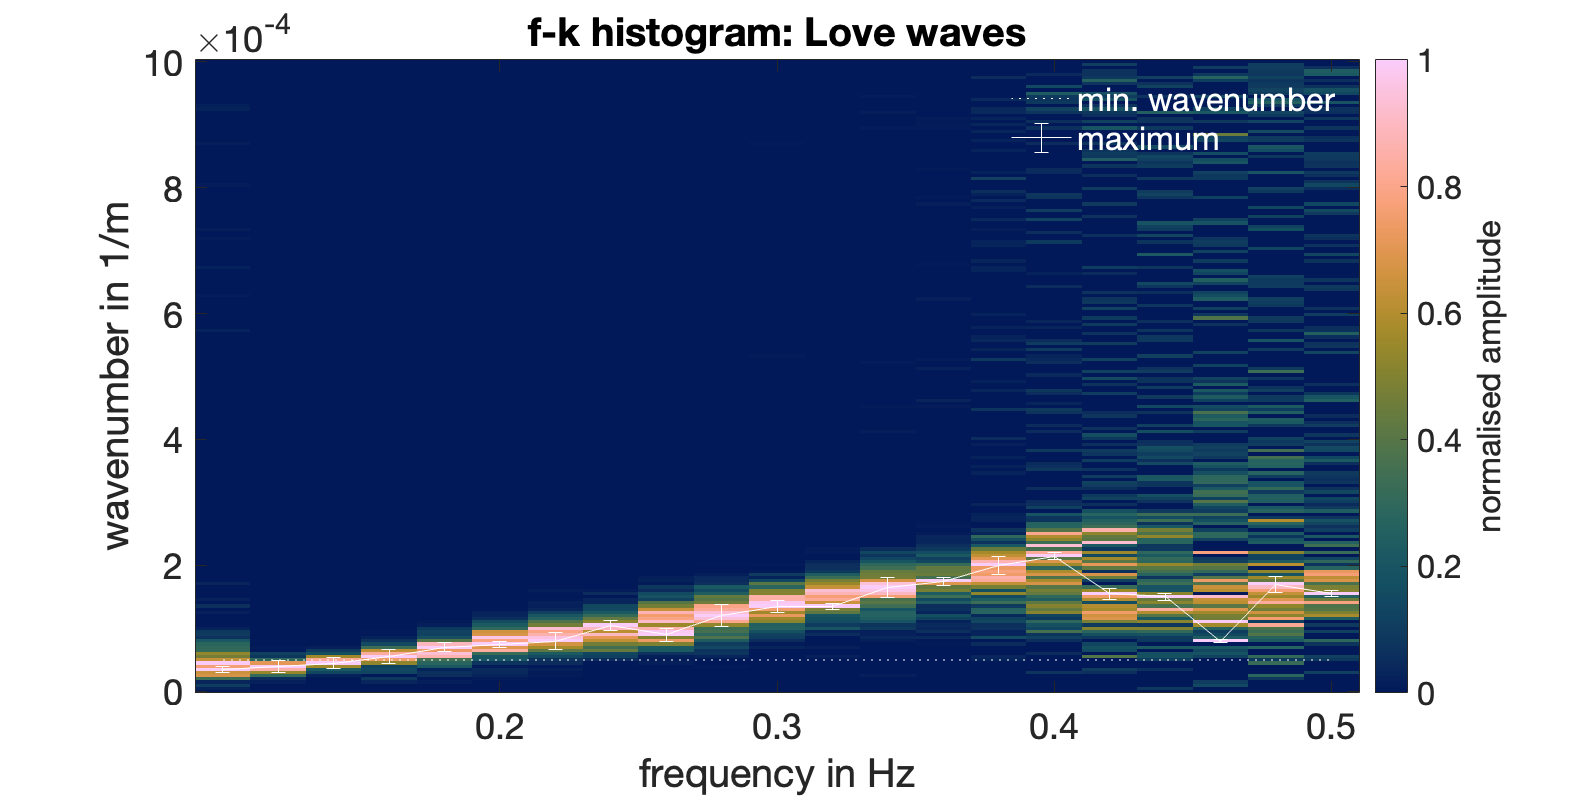

if plotkhisto
    
cmap = crameri('batlow');

% Retrograde Rayleigh
if histonorm
    k_retro_amp = k_retro_amp./max(k_retro_amp,[],2);
    clabel = 'normalised amplitude';
else
    clabel = 'cummulative amplitude';
end
figure('Color','white','Position',[2000 10 1000 500])
imagesc(freqs,kbins,k_retro_amp');
line([min(freqs) max(freqs)],[procpars.kmin procpars.kmin],'Color','w','LineStyle',':')
set(gca,'ydir','normal')
xlabel('frequency in Hz')
ylabel('wavenumber in 1/m')
set(gca,'xtick',0.2:0.1:1.2,'Fontsize',18)
colormap(cmap)
cr = colorbar;
cr.Label.String = clabel;
title('f-k histogram: retrograde Rayleigh waves')
legend('min. wavenumber')
if exist('kh_retro_max','var')
    hold on
    errorbar(freqs(prmask > 0),kh_retro_max(prmask > 0),wmax_retro_k(prmask > 0),'w')
    legend('min. wavenumber','maximum')
else
    warning('No retrograde Rayleigh waves picked for SNR = %1.2f',SNR);
end
lhisto=legend('boxoff');
lhisto.TextColor = [1 1 1];

if savefigs
    fname = sprintf('%s/08_khisto_retro_%s_%s_%s.png',...
        dir_out,maxflag,nw,indate);
    print(fname,'-dpng')
end

% Prograde Rayleigh
if histonorm
    k_pro_amp = k_pro_amp./max(k_pro_amp,[],2);
    clabel = 'normalised amplitude';
else
    clabel = 'cummulative amplitude';
end
figure('Color','white','Position',[2000 10 1000 500])
imagesc(freqs,kbins,k_pro_amp');
line([min(freqs) max(freqs)],[procpars.kmin procpars.kmin],'Color','w','LineStyle',':')
set(gca,'ydir','normal')
xlabel('frequency in Hz')
ylabel('wavenumber in 1/m')
set(gca,'xtick',0.2:0.1:1.2,'Fontsize',18)
colormap(cmap)
cr = colorbar;
cr.Label.String = clabel;
title('f-k histogram: prograde Rayleigh waves')
legend('min. wavenumber')
if exist('kh_pro_max','var')
    hold on
    errorbar(freqs(ppmask > 0),kh_pro_max(ppmask > 0),wmax_pro_k(ppmask > 0),'w')
    legend('min. wavenumber','maximum')
else
    warning('No prograde Rayleigh waves picked for SNR = %1.2f',SNR);
end
lhisto=legend('boxoff');
lhisto.TextColor = [1 1 1];

if savefigs
    fname = sprintf('%s/09_khisto_pro_%s_%s_%s.png',...
        dir_out,maxflag,nw,indate);
    print(fname,'-dpng')
end
    
% Love
if histonorm
    k_love_amp = k_love_amp./max(k_love_amp,[],2);
    clabel = 'normalised amplitude';
else
    clabel = 'cummulative amplitude';
end
figure('Color','white','Position',[2000 10 1000 500])
imagesc(freqs,kbins,k_love_amp');
line([min(freqs) max(freqs)],[procpars.kmin procpars.kmin],'Color','w','LineStyle',':')
set(gca,'ydir','normal')
xlabel('frequency in Hz')
ylabel('wavenumber in 1/m')
set(gca,'xtick',0.2:0.1:1.2,'Fontsize',18)
colormap(cmap)
cr = colorbar;
cr.Label.String = clabel;
title('f-k histogram: Love waves')
legend('min. wavenumber')
if exist('kh_love_max','var')
    hold on
    errorbar(freqs(plmask > 0),kh_love_max(plmask > 0),wmax_love_k(plmask > 0),'w')
    legend('min. wavenumber','maximum')
else
    warning('No Love waves picked for SNR = %1.2f',SNR);
end
lhisto=legend('boxoff');
lhisto.TextColor = [1 1 1];

if savefigs
    fname = sprintf('%s/10_khisto_love_%s_%s_%s.png',...
        dir_out,maxflag,nw,indate);
    print(fname,'-dpng')
end

end % if plotkhisto

## Plot velocity dispersion curves

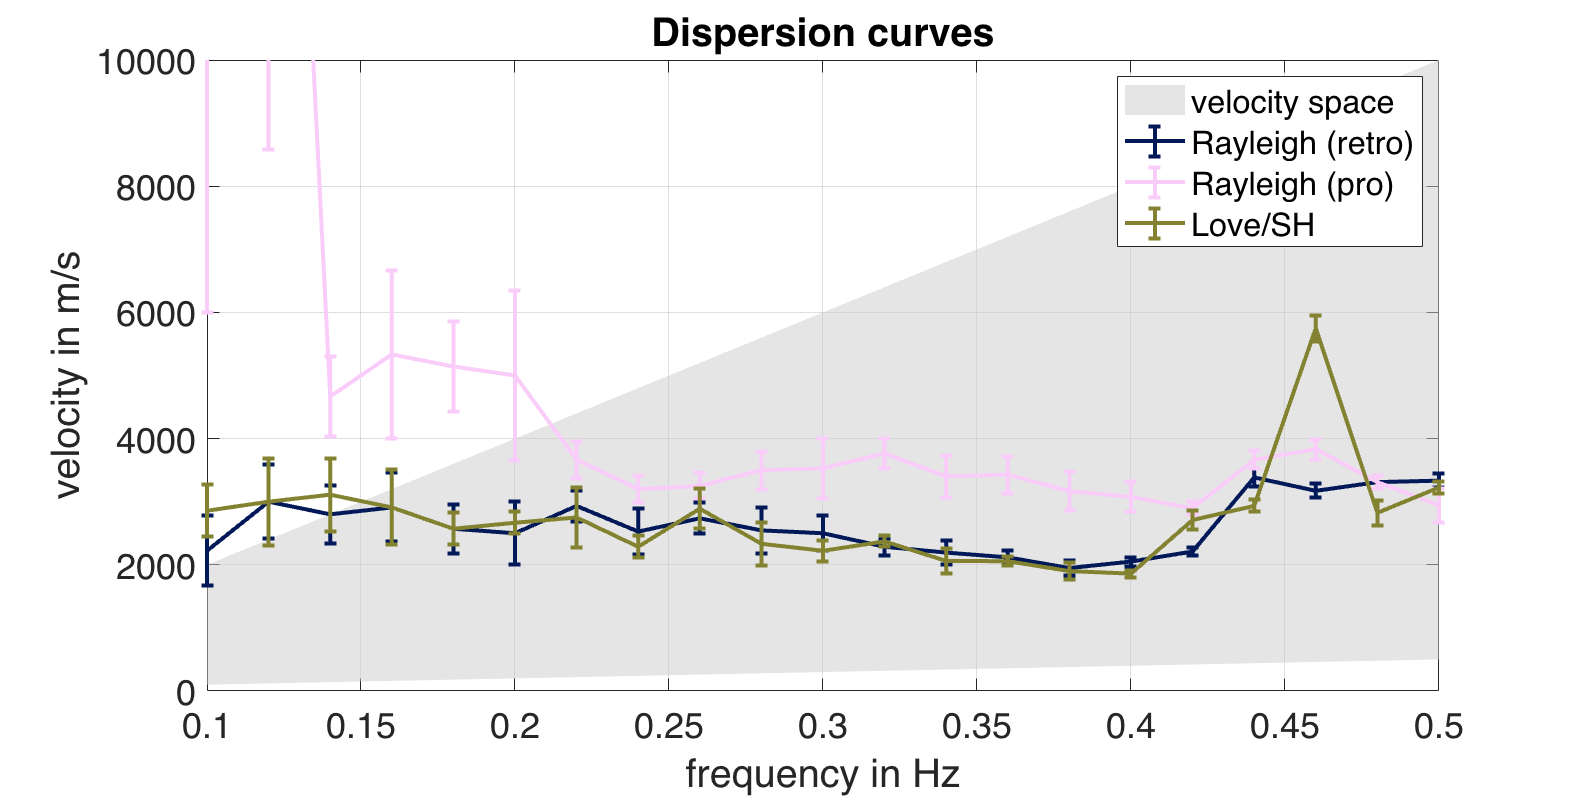

if plotvdisp
    
% Compute velocities from maxima in wavenumber histogram

% Velocity limits from kmin and kmax
vmin = freqs/kmax;
vmax = freqs/procpars.kmin;
% Prepare plotting of shaded area
inbetween = [vmin fliplr(vmax)];
f2 = [freqs fliplr(freqs)];

% Retrograde Rayleigh
if exist('kh_retro_max','var')==1
vretro = freqs(prmask > 0)./kh_retro_max(prmask > 0);
wmax_retro_v = wmax_retro_k(prmask > 0)./kh_retro_max(prmask > 0) .* vretro;
end

% Prograde Rayleigh
if exist('kh_pro_max','var')==1
vpro = freqs(ppmask > 0)./kh_pro_max(ppmask > 0);
wmax_pro_v = wmax_pro_k(ppmask > 0)./kh_pro_max(ppmask > 0) .* vpro;
end

% Love
if exist('kh_love_max','var')==1
vlove = freqs(plmask > 0)./kh_love_max(plmask > 0);
wmax_love_v = wmax_love_k(plmask > 0)./kh_love_max(plmask > 0) .* vlove;
end

figure('Color','white','Position',[2000 10 1000 500])
legend('-DynamicLegend')
hold all
fill(f2,inbetween,[0.8 0.8 0.8],'DisplayName','velocity space','FaceAlpha',0.5,'LineStyle','none')
if exist('vretro','var')==1; e1 = errorbar(freqs(prmask>0),vretro,wmax_retro_v,...
        'LineWidth',2,'Color',batlowS(1,:),'DisplayName','Rayleigh (retro)'); end
if exist('vpro','var')==1; e2 = errorbar(freqs(ppmask>0),vpro,wmax_pro_v,...
        'LineWidth',2,'Color',batlowS(2,:),'DisplayName','Rayleigh (pro)'); end
if exist('vlove','var')==1; e3 = errorbar(freqs(plmask>0),vlove,wmax_love_v,...
        'LineWidth',2,'Color',batlowS(3,:),'DisplayName','Love/SH'); end
ylim([0 max(vmax)])
title('Dispersion curves')
xlabel('frequency in Hz')
ylabel('velocity in m/s')
set(gca,'Fontsize',18)
box on
grid on
xlim([freqs(1) freqs(end)])

if savefigs
    fname = sprintf('%s/11_disp_%s_%s_%s.png',...
        dir_out,maxflag,nw,indate);
    print(fname,'-dpng')
end

end

## Plot direction of arrival (azimuth)

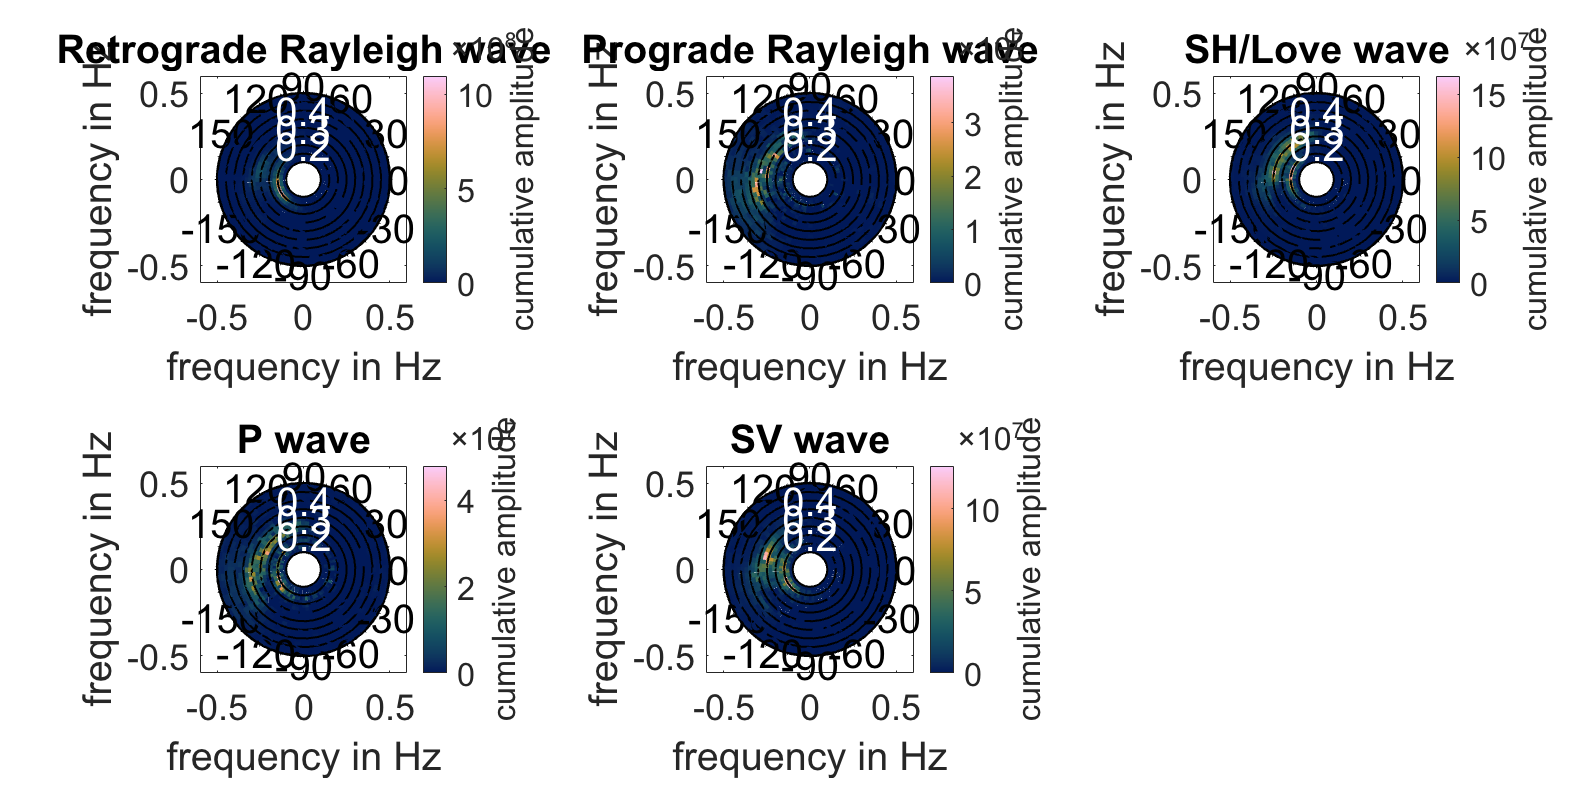

if plotDOA

cmap = crameri('batlow');    

% Histograms
clear N*

% Define azimuth bins
astep = max(1,abs(procpars.agrid(1)-procpars.agrid(2))); % minimum is 1
amin = min(procpars.agrid)-floor(astep/2);
amax = max(procpars.agrid)+ceil(astep/2);
abins = amin:astep:amax;

azi_retro_amp = zeros(length(freqs),length(abins)-1);
azi_pro_amp = zeros(length(freqs),length(abins)-1);
azi_love_amp = zeros(length(freqs),length(abins)-1);
azi_sv_amp = zeros(length(freqs),length(abins)-1);
azi_p_amp = zeros(length(freqs),length(abins)-1);

for i = 1:length(freqs)
    
    [Nretro,binretro,idxretro] = histcounts(round(kth_retro_all{i}*180/pi),abins);    
	[Npro,binpro,idxpro] = histcounts(round(kth_pro_all{i}*180/pi),abins);
	[Nlove,binlove,idxlove] = histcounts(round(kth_love_all{i}*180/pi),abins);
    [Nsv,binsv,idxsv] = histcounts(round(kth_sv_all{i}*180/pi),abins);
    [Np,binp,idxp] = histcounts(round(kth_p_all{i}*180/pi),abins);

    % Considering beam response amplitude in DOA histogram
    
    Aretro = zeros(length(abins)-1,1);
    Apro = zeros(length(abins)-1,1);
    Alove = zeros(length(abins)-1,1);
    Asv = zeros(length(abins)-1,1);
    Ap = zeros(length(abins)-1,1);

    if isempty(idxretro) == 0
        Aretro = accumarray(idxretro',a_retro_all{i});
        azi_retro_amp(i,1:length(Aretro)) = Aretro;
    end
    
    if isempty(idxpro) == 0
        Apro = accumarray(idxpro',a_pro_all{i});
        azi_pro_amp(i,1:length(Apro)) = Apro;
    end
    
    if isempty(idxlove) == 0
        Alove = accumarray(idxlove',a_love_all{i});
        azi_love_amp(i,1:length(Alove)) = Alove;
    end
    
    if isempty(idxsv) == 0
        Asv = accumarray(idxsv',a_sv_all{i});
        azi_sv_amp(i,1:length(Asv)) = Asv;
    end
    
    if isempty(idxp) == 0
        Ap = accumarray(idxp',a_p_all{i});
        azi_p_amp(i,1:length(Ap)) = Ap;
    end
end

xmax = max(freqs)+0.2*max(freqs);

figure('Color','white','Position',[50 50 1400 700]);

% Retrograde Rayleigh
tldoa = tiledlayout(2,3);
nexttile
Nretroshift = azi_retro_amp;
Nretroshift(:,end+1)=0; % adding additional column to prevent overlap (bug in polarplot3d)
polarplot3d(Nretroshift,'RadialRange',[min(freqs) max(freqs)],'PlotType','surfn','PolarGrid',{8 0},...
    'PolarDirection','ccw','TickSpacing',15,'RadLabels',3,'RadLabelLocation',{90 'top'},'RadLabelColor','w','AngularRange',[amin,amax]*pi/180);
view(0,90)
colormap(cmap)
axis equal
box on
grid off
set(gca,'Fontsize',18)
title('Retrograde Rayleigh wave')
xlim([-xmax xmax])
ylim([-xmax xmax])
xlabel('frequency in Hz')
ylabel('frequency in Hz')
cb = colorbar;
cb.Label.String = 'cumulative amplitude';

% Prograde Rayleigh
nexttile
Nproshift = azi_pro_amp;
Nproshift(:,end+1)=0;
polarplot3d(Nproshift,'RadialRange',[min(freqs) max(freqs)],'PlotType','surfn','PolarGrid',{8 0},...
    'PolarDirection','ccw','TickSpacing',15,'RadLabels',3,'RadLabelLocation',{90 'top'},'RadLabelColor','w','AngularRange',[amin,amax]*pi/180);
view(0,90)
colormap(cmap)
axis equal
box on
grid off
set(gca,'Fontsize',18)
title('Prograde Rayleigh wave')
xlim([-xmax xmax])
ylim([-xmax xmax])
xlabel('frequency in Hz')
ylabel('frequency in Hz')
cb = colorbar;
cb.Label.String = 'cumulative amplitude';

% SH/Love wave
nexttile
Nloveshift = azi_love_amp;
Nloveshift(:,end+1)=0;
polarplot3d(Nloveshift,'RadialRange',[min(freqs) max(freqs)],'PlotType','surfn','PolarGrid',{8 0},...
    'PolarDirection','ccw','TickSpacing',15,'RadLabels',3,'RadLabelLocation',{90 'top'},'RadLabelColor','w','AngularRange',[amin,amax]*pi/180);
view(0,90)
colormap(cmap)
axis equal
box on
grid off
set(gca,'Fontsize',18)
title('SH/Love wave')
xlim([-xmax xmax])
ylim([-xmax xmax])
xlabel('frequency in Hz')
ylabel('frequency in Hz')
cb = colorbar;
cb.Label.String = 'cumulative amplitude';

% P wave
nexttile
Npshift = azi_p_amp;
Npshift(:,end+1)=0;
polarplot3d(Npshift,'RadialRange',[min(freqs) max(freqs)],'PlotType','surfn','PolarGrid',{8 0},...
    'PolarDirection','ccw','TickSpacing',15,'RadLabels',3,'RadLabelLocation',{90 'top'},'RadLabelColor','w','AngularRange',[amin,amax]*pi/180);
view(0,90)
colormap(cmap)
axis equal
box on
grid off
set(gca,'Fontsize',18)
title('P wave')
xlim([-xmax xmax])
ylim([-xmax xmax])
xlabel('frequency in Hz')
ylabel('frequency in Hz')
cb = colorbar;
cb.Label.String = 'cumulative amplitude';

% SV wave
nexttile
Nsvshift = azi_sv_amp;
Nsvshift(:,end+1)=0;
polarplot3d(Nsvshift,'RadialRange',[min(freqs) max(freqs)],'PlotType','surfn','PolarGrid',{8 0},...
    'PolarDirection','ccw','TickSpacing',15,'RadLabels',3,'RadLabelLocation',{90 'top'},'RadLabelColor','w','AngularRange',[amin,amax]*pi/180);
view(0,90)
colormap(cmap)
axis equal
box on
grid off
set(gca,'Fontsize',18)
title('SV wave')
xlim([-xmax xmax])
ylim([-xmax xmax])
xlabel('frequency in Hz')
ylabel('frequency in Hz')
cb = colorbar;
cb.Label.String = 'cumulative amplitude';

if savefigs
    fname = sprintf('%s/12_DOA_%s_%s_%s.png',...
        dir_out,maxflag,nw,indate);
    print(fname,'-dpng')
end

end

## EOF